# Minesweeper Game Details

#### Terminology

- **Revealing a Space**: Mouse clicking on a space to uncover its value.

- **Flagging a Space**: Placing a flag on a space that you believe is a mine.

- **Mine Space**: A space that contains a mine (value = -1).

- **Safe Space**: Any space that doesn't contain a mine (value = 0,1,2,3,4,5,6,7,8).

- **Adjacent Space**: Two spaces that are touching (corners included) are said to be adjacent.

- **Blank Space**: Not adjacent to a mine (value = 0).

- **Flagged Space**: A space that has been flagged.

- **Revealed Space**: A space that has been revealed.

#### Rules

- The game is played by either revealing or flagging one space at a time. 

- Revealing a mine (value = -1) ends the game.

- Revealing a non-blank safe space (value = 1,2,3,4,5,6,7,8), reveals just that space.

- Revealing a blank space, reveals all adjacent safe spaces. This will chain into more reveals if an adjacent blank space is revealed in this way.

- Revealing all safe spaces and flagging all mines wins the game.

#### Examples

Suppose we start a game with a 4 x 4 grid and 2 mines, like so:

game_matrix = [1 1 0 0;-1 2 1 0;2 -1 1 0;1 1 1 0];
revealed = [0 0 0 0;0 0 0 0;0 0 0 0;0 0 0 0];
flagged = [0 0 0 0;0 0 0 0;0 0 0 0;0 0 0 0];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    0    0    0    0    0    0    0
    -1     2     1     0    0    0    0    0    0    0    0    0
     2    -1     1     0    0    0    0    0    0    0    0    0
     1     1     1     0    0    0    0    0    0    0    0    0


Initial graphical game board:

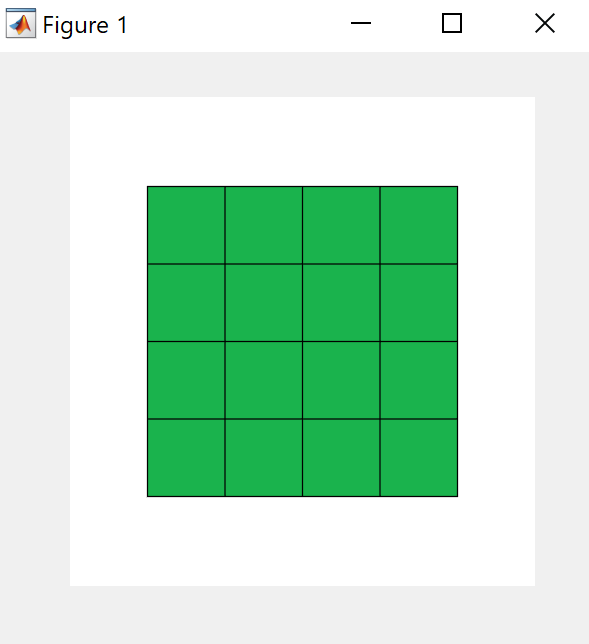

Clicking on space (2,3) reveals it because it is a non-blank safe-space

revealed = [0 0 0 0;0 0 1 0;0 0 0 0;0 0 0 0];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    0    0    0    0    0    0    0
    -1     2     1     0    0    0    1    0    0    0    0    0
     2    -1     1     0    0    0    0    0    0    0    0    0
     1     1     1     0    0    0    0    0    0    0    0    0


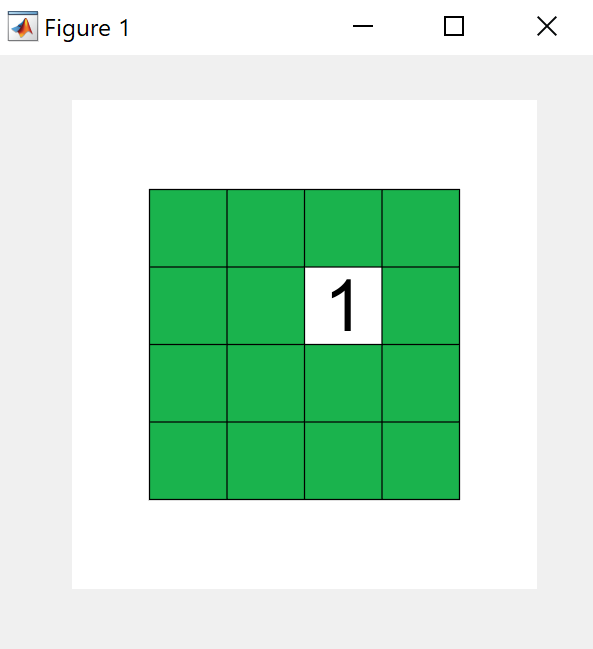

Clicking on space (3,3), (4,1), and (4,2) does the same thing.

revealed = [0 0 0 0;0 0 1 0;0 0 1 0;1 1 0 0];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    0    0    0    0    0    0    0
    -1     2     1     0    0    0    1    0    0    0    0    0
     2    -1     1     0    0    0    1    0    0    0    0    0
     1     1     1     0    1    1    0    0    0    0    0    0


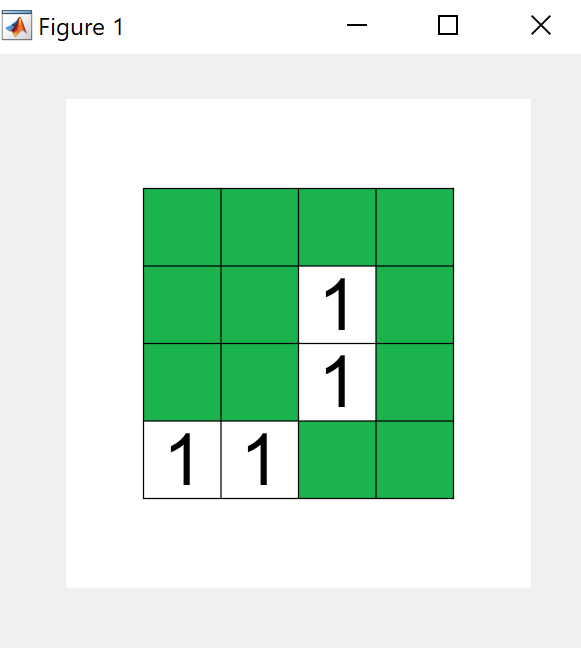

Now, clicking on space (1,4) (a blank space) causes itself as well as (1,3) and (2,4) to be revealed since they are adjacent safe spaces to a blank space.  

Since (1,3) is also blank, spaces (1,2) and (2,2) are also revealed, but these are non-blank safe spaces so the reveal chain stops.  

However, (2,4) from the original reveal was also blank, so the reveal chain continues down to (3,4), which is also blank, so (4,3) and (4,4) must also be revealed.

In summary, clicking on space (1,4) reveals the 8 spaces: (1,4), (1,3), (2,4), (1,2), (2,2), (3,4), (4,3), and (4,4).

revealed = [0 1 1 1;0 0 1 1;0 0 1 1;1 1 1 1];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    1    1    1    0    0    0    0
    -1     2     1     0    0    0    1    1    0    0    0    0
     2    -1     1     0    0    0    1    1    0    0    0    0
     1     1     1     0    1    1    1    1    0    0    0    0


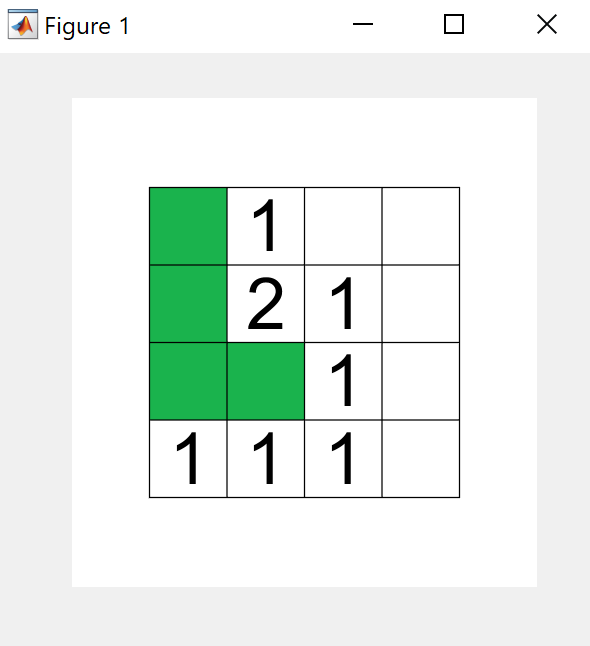

You may want to flag space (3,2) because you think a mine is under that space. In this case you update the `flagged` matrix but not the `revealed` matrix.

flagged = [0 0 0 0;0 0 0 0;0 1 0 0;0 0 0 0];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    1    1    1    0    0    0    0
    -1     2     1     0    0    0    1    1    0    0    0    0
     2    -1     1     0    0    0    1    1    0    1    0    0
     1     1     1     0    1    1    1    1    0    0    0    0


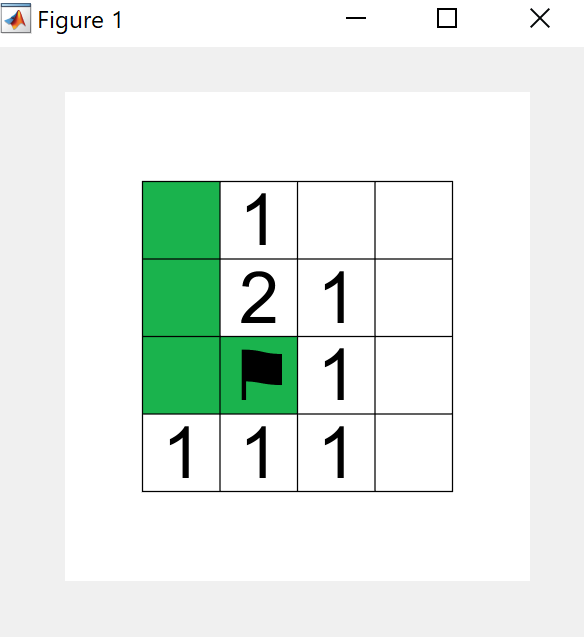

Logically since the bottom left space has a value of 1, logic tell you that there can't be a mine in the space directly above it. So you reveal space (3,1).

revealed = [0 1 1 1;0 1 1 1;1 0 1 1;1 1 1 1];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    1    1    1    0    0    0    0
    -1     2     1     0    0    1    1    1    0    0    0    0
     2    -1     1     0    1    0    1    1    0    1    0    0
     1     1     1     0    1    1    1    1    0    0    0    0


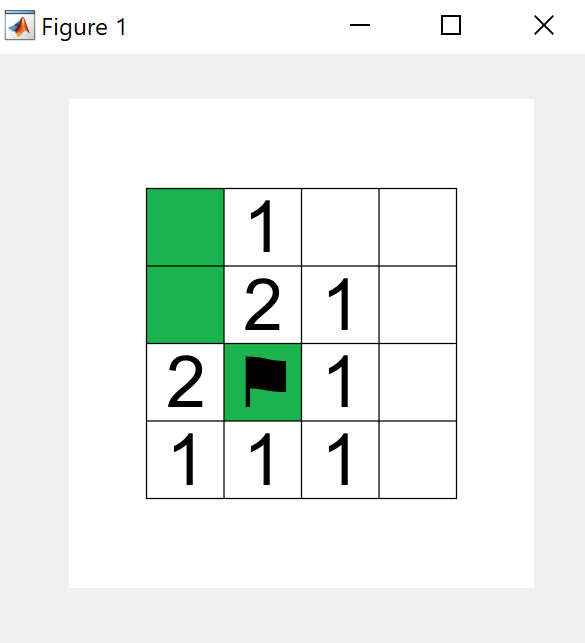

Clearly, a mine must be above the 2 you just revealed, but suppose you didn't see that and you revealed space (2,1).

revealed = [0 1 1 1;1 1 1 1;1 0 1 1;1 1 1 1];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    0    1    1    1    0    0    0    0
    -1     2     1     0    1    1    1    1    0    0    0    0
     2    -1     1     0    1    0    1    1    0    1    0    0
     1     1     1     0    1    1    1    1    0    0    0    0


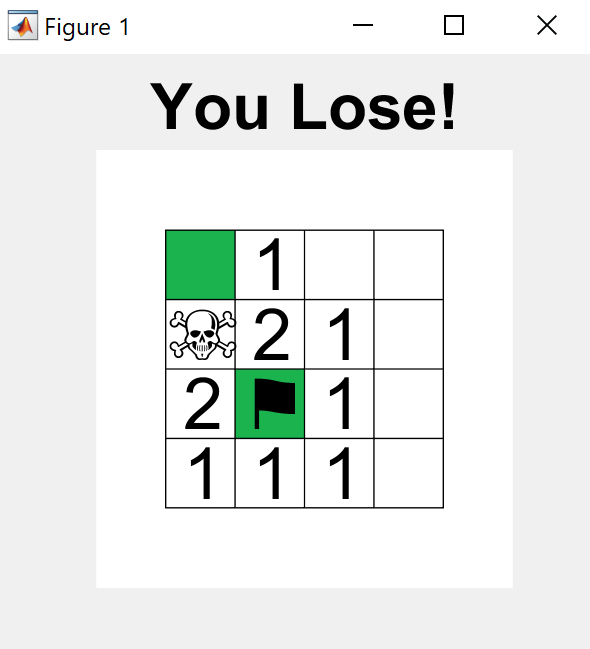

Reversing time, if you instead flagged space (2,1), and revealed space (1,1), you would win.

revealed = [1 1 1 1;0 1 1 1;1 0 1 1;1 1 1 1];
flagged  = [0 0 0 0;1 0 0 0;0 1 0 0;0 0 0 0];
table(game_matrix,revealed,flagged)

ans = 4×3 table
        game_matrix             revealed            flagged     
    ____________________    ________________    ________________

     1     1     0     0    1    1    1    1    0    0    0    0
    -1     2     1     0    0    1    1    1    1    0    0    0
     2    -1     1     0    1    0    1    1    0    1    0    0
     1     1     1     0    1    1    1    1    0    0    0    0


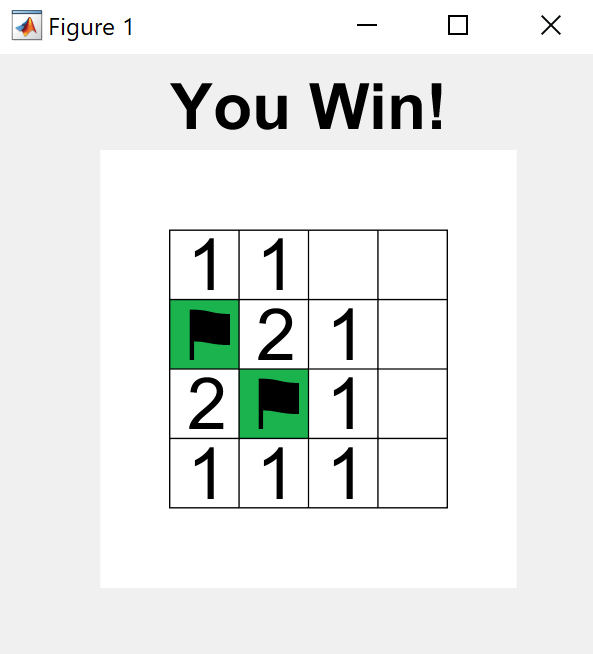

**Flagging a Space**

Since MATLAB's `ginput` command does not have a right-click option, we have to be a little clever with how to distinguish between flagging a space and revealing a space.  To overcome this limitation, we will separate each space into two regions.

- A mouse click in the bottom left quarter of a space will trigger the flag action.

- A mouse click anywhere else will trigger a reveal action.

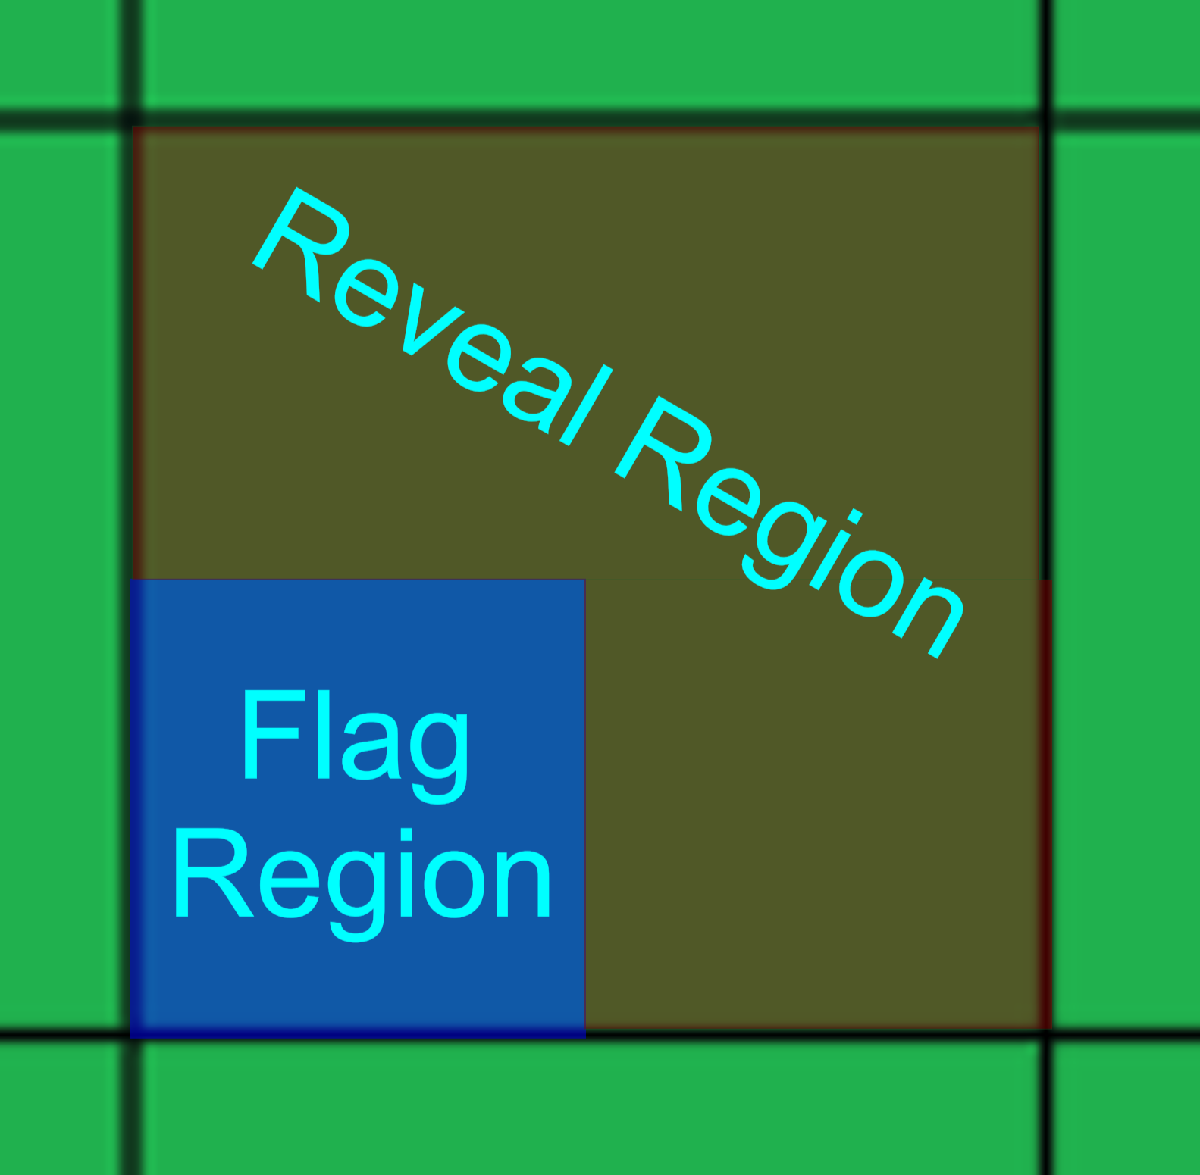

Your code must determine which region was clicked and perform the appropriate action.

**Revealing a Blank Space Code Strategy**

The most difficult part of the Minesweeper game will likely be the blank chain reveal helper function.

So this section will go over one possible strategy.

Inputs:

- `row` (row location of initial blank clicked space)

- `col` (column location of initial blank clicked space)

- `field` (mine field)

- `revealed` (shows which spaces have been revealed so far)

*Note: *`row`* and *`col`* correspond to the mine field matrix not the (x,y) coordinates on the game figure.*

Output:

- `to_reveal` (matrix containing all the location that should be revealed after a blank space is revealed)

Helpful Variables:

- Define a variable, say `reveal_chain`, that has the job of storing a list of new safe locations resulting from a reveal chain.

- Define a variable, say `explored`, to represent which spaces have been processed and added to the "master list" output variable.

Strategy:

It is assumed that if this program was called, then a blank space @ (row,col) was clicked. So start by adding this blank to the `reveal_chain` and mark this location in as being `explored.`

Loop as long as the `reveal_chain` still contains values to process.

Within the loop, perform the following tasks:

- add the first location in `reveal_chain` to the "master list" (output variable).

- if that value is blank, then you need to look for all adjacent safe spaces to that space and add them to the bottom of the `reveal_chain`. Additionally, to need to mark them as `explored`.

- since the top location, in `reveal_chain,` has been completely processed, delete it from `reveal_chain`.

The loop above processes only the first location in `reveal_chain` and then deletes it at the end. Keep in mind that the loop also adds multiple values to the bottom of `reveal_chain`, so the length of `reveal_chain` is both increasing and decreasing throughout the loop.

If you use this strategy, I recommend preallocating the "master list" (output list), but I do not recommend trying to preallocate the `reveal_chain` list since we are constantly deleting the top and adding stuff to the bottom. Ignore the MATLAB preallocation  warning (Walsh).